# Lab9: Process reconstruction free from any constraints and assumptions

Team1: Dmitry Shadrin and Eugenii Israelit, Skoltech

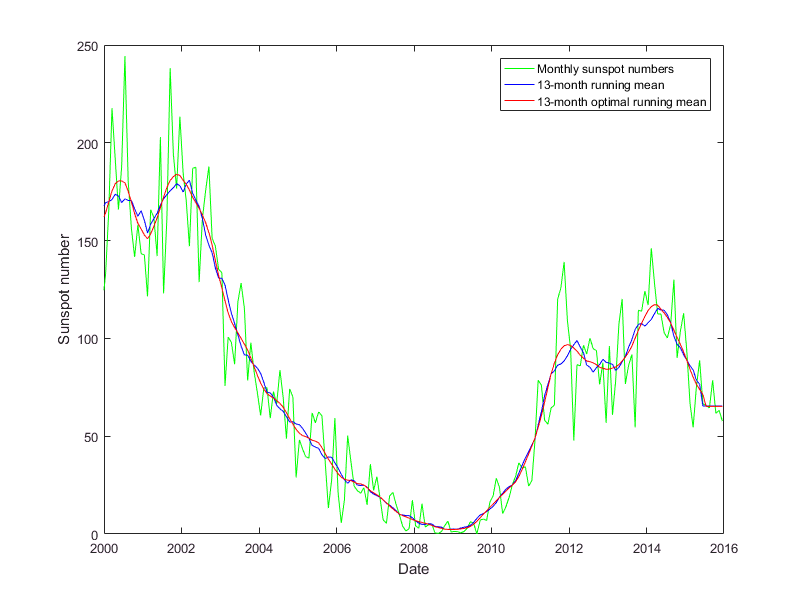

clc; clear; close all;
Data = importdata('sunspot.mat');

SunSpots = Data(:,4);
Time = Data(:,3);

SmoothSunSpots = smooth(SunSpots, 13)';
optimalSmoothedSunSpot = smoothOptimal(SunSpots, 0.01);

figure ('position', [0, 0, 800, 600]);
plot(Time, SunSpots, 'green')
hold on
plot(Time, SmoothSunSpots, 'blue')
plot(Time, optimalSmoothedSunSpot, 'red')
lg = legend('Monthly sunspot numbers', '13-month running mean', '13-month optimal running mean'); 
ylabel('Sunspot number') 
xlabel('Date')
axis([2000 2016 0 250])

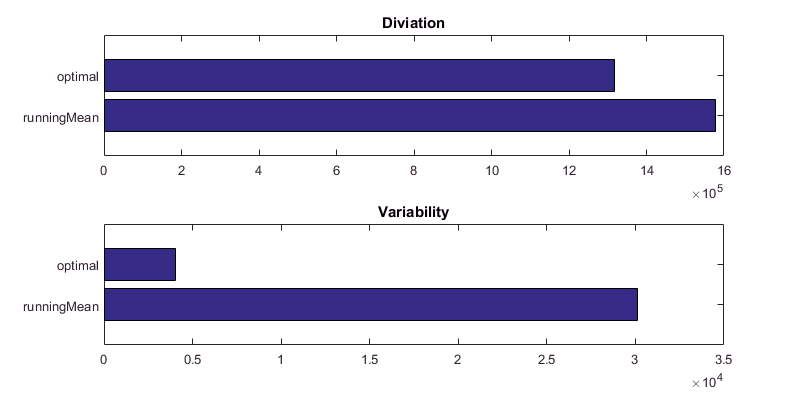



runningMeanDiviation = calcDiviation(SmoothSunSpots, SunSpots);
runningMeanVariation = calcVariability(SmoothSunSpots);
optimalDiviation = calcDiviation(optimalSmoothedSunSpot, SunSpots);
optimalVariation = calcVariability(optimalSmoothedSunSpot);
dataVariability = calcVariability(SunSpots);

figure ('position', [0, 0, 800, 400]);
label = cell(1,3);
label{1}='runningMean'; label{2}='optimal'; label{3}='original Data';

subplot(2,1,1)
barh([runningMeanDiviation; optimalDiviation ])
title('Diviation')

set(gca,'yticklabel', label)
subplot(2,1,2)
barh([runningMeanVariation optimalVariation])%+  dataVariability
title('Variability')
set(gca,'yticklabel', label)

**Conclusion** : "Optimal Smoothing" method provides less Diviation and Variability comparing with "13-months running mean method"